# Copper Solvent Extraction

Pieter Leon van den Berg

22684166

25 April 2022

Final Year Project (C) 478

Supervisor: Dr Cripwell

### Copper solvent extraction

Dynamic model of a copper solvent extraction plant to use for fault detection.

### Setup

clear;
clc;

### Simulation Time

simulation_time = 700*60*60; % [s] Run the model for 700 hours
sampling_time   = 30;        % [s] Simulate the process every 30 seconds

## Parameters

### Mass transfer coefficients

K_mass_1 = 1.13;    % [1/s]
K_mass_2 = 0.0186;  % [1/s]
K_mass_3 = 0.672;   % [1/s]
K_mass_4 = 0.398;   % [1/s]

### Equilibrium concentrations

% Extraction
C_org_max = 22.73;  % [g/L]
K_eq_ext  = 88.00;  % [L/g]

% Stripping
C_aq_max  = 94.34;  % [g/L]
K_eq_str  = 2.16;   % [L/g]

### Valve Sizing

% Organic
fLO_max   = 556;    % [L/s]

% Electrolyte
fLE_max   = 390;    % [L/s]

### Mixer volumes

V1 = 1400;          % [L]
V2 = 1400;          % [L]
V3 = 1400;          % [L]  
V4 = 1400;          % [L]

### Settler delays

t1 = 900;           % [s]
t2 = 900;           % [s]
t3 = 900;           % [s]
t4 = 900;           % [s]

## Steady-state Values

### Concentrations

% PLS
cPLS_ss  = 7;               % [g/L]

% Aqueous
C1_aq_ss = 0.007594752;     % [g/L]
C2_aq_ss = 0.006420935;     % [g/L]
C3_aq_ss = 0.033235766;     % [g/L]

% Organic
C1_org_ss = 7.876910289;    % [g/L]
C2_org_ss = 7.919777096;    % [g/L]
C3_org_ss = 14.87991304;    % [g/L]
C4_org_ss = 0.885172472;    % [g/L]

% Electrolyte
cLE_ss   = 35;              % [g/L]
C1_el_ss = 54.95809839;     % [g/L]

### Flowrates

% PLS
fPLSP_ss = 278;    % [L/s]
fPLSS_ss = 278;    % [L/s]

### Valves

vLO_ss   = 0.5;     % [-]
vLE_ss   = 0.5;     % [-]

## Run the Simulink Model

simulation_results = sim('process_model/copper_solvent_extraction_model_simulink');

## Plot the Simulation Results

### Setup the time

% Convert the simulation time from seconds to hours
model_time = simulation_results.tout / (60*60);

### Plot the organic concentrations

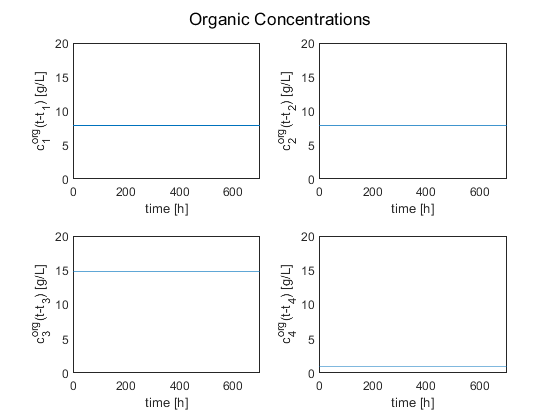

% Create the group of organic concentrations
figure()
sgtitle('Organic Concentrations')

% Plot C1_org_delay
subplot(2,2,1)
plot(model_time, simulation_results.C1_org_delay.Data)
ylabel("c_{1}^{org}(t-t_{1}) [g/L]")
xlabel("time [h]")
ylim([0 20])
xlim([0 model_time(end)])

% Plot C2_org_delay
subplot(2,2,2)
plot(model_time, simulation_results.C2_org_delay.Data)
ylabel("c_{2}^{org}(t-t_{2}) [g/L]")
xlabel("time [h]")
ylim([0 20])
xlim([0 model_time(end)])

% Plot C3_org_delay
subplot(2,2,3)
plot(model_time, simulation_results.C3_org_delay.Data)
ylabel("c_{3}^{org}(t-t_{3}) [g/L]")
xlabel("time [h]")
ylim([0 20])
xlim([0 model_time(end)])

% Plot C4_org_delay
subplot(2,2,4)
plot(model_time, simulation_results.C4_org_delay.Data)
ylabel("c_{4}^{org}(t-t_{4}) [g/L]")
xlabel("time [h]")
ylim([0 20])
xlim([0 model_time(end)])

### Plot the aqueous concentrations

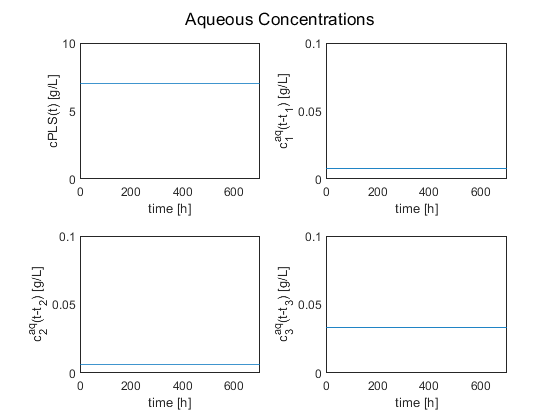

% Create the group of aqueous concentrations
figure()
sgtitle('Aqueous Concentrations')

% Plot cPLS
subplot(2,2,1)
plot(model_time, simulation_results.cPLS.Data)
ylabel("cPLS(t) [g/L]")
xlabel("time [h]")
ylim([0 10])
xlim([0 model_time(end)])

% Plot C1_aq_delay
subplot(2,2,2)
plot(model_time, simulation_results.C1_aq_delay.Data)
ylabel("c_{1}^{aq}(t-t_{1}) [g/L]")
xlabel("time [h]")
ylim([0 0.1])
xlim([0 model_time(end)])

% Plot C2_aq_delay
subplot(2,2,3)
plot(model_time, simulation_results.C2_aq_delay.Data)
ylabel("c_{2}^{aq}(t-t_{2}) [g/L]")
xlabel("time [h]")
ylim([0 0.1])
xlim([0 model_time(end)])

% Plot C3_aq_delay
subplot(2,2,4)
plot(model_time, simulation_results.C3_aq_delay.Data)
ylabel("c_{3}^{aq}(t-t_{3}) [g/L]")
xlabel("time [h]")
ylim([0 0.1])
xlim([0 model_time(end)])

### Plot the electrolyte concentrations

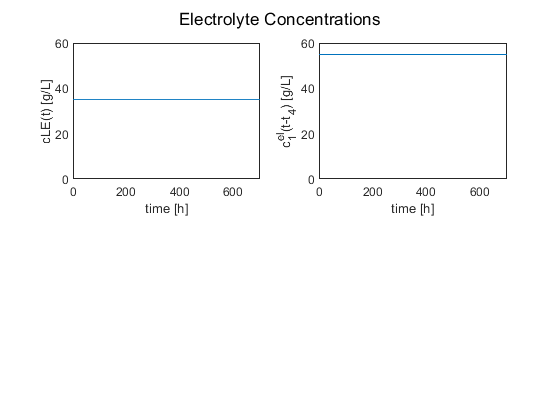

% Create the group of electrolyte concentrations
figure()
sgtitle('Electrolyte Concentrations')

% Plot cLE
subplot(2,2,1)
plot(model_time, simulation_results.cLE.Data)
ylabel("cLE(t) [g/L]")
xlabel("time [h]")
ylim([0 60])
xlim([0 model_time(end)])

% Plot C1_el_delay
subplot(2,2,2)
plot(model_time, simulation_results.C1_el_delay.Data)
ylabel("c_{1}^{el}(t-t_{4}) [g/L]")
xlabel("time [h]")
ylim([0 60])
xlim([0 model_time(end)])

### Plot the flowrates

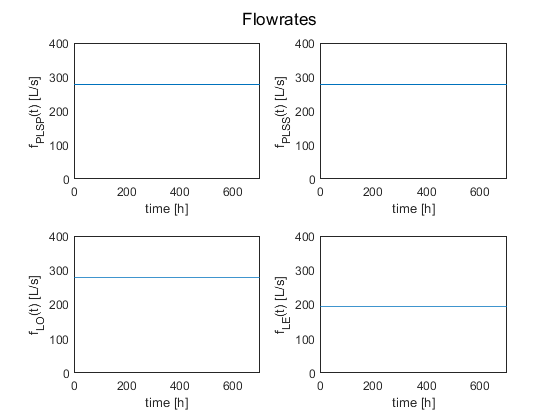

% Create the group of flowrates
figure()
sgtitle('Flowrates')

% Plot fPLSP
subplot(2,2,1)
plot(model_time, simulation_results.fPLSP.Data)
ylabel("f_{PLSP}(t) [L/s]")
xlabel("time [h]")
ylim([0 400])
xlim([0 model_time(end)])

% Plot fPLSS
subplot(2,2,2)
plot(model_time, simulation_results.fPLSS.Data)
ylabel("f_{PLSS}(t) [L/s]")
xlabel("time [h]")
ylim([0 400])
xlim([0 model_time(end)])

% Plot fLO
subplot(2,2,3)
plot(model_time, simulation_results.fLO.Data)
ylabel("f_{LO}(t) [L/s]")
xlabel("time [h]")
ylim([0 400])
xlim([0 model_time(end)])

% Plot fLE
subplot(2,2,4)
plot(model_time, simulation_results.fLE.Data)
ylabel("f_{LE}(t) [L/s]")
xlabel("time [h]")
ylim([0 400])
xlim([0 model_time(end)])

## Save the Simulation data to a CSV file

### Write the data to a table

% Create a blank table
SIMULATION_TABLE = table();

% Add the simulation time
SIMULATION_TABLE.time = simulation_results.tout;

% Add the flow rates
SIMULATION_TABLE.fPLSP = simulation_results.fPLSP.Data;
SIMULATION_TABLE.fPLSS = simulation_results.fPLSS.Data;
SIMULATION_TABLE.fLO   = simulation_results.fLO.Data;
SIMULATION_TABLE.fLE   = simulation_results.fLE.Data;

% Add the control valve positions
SIMULATION_TABLE.vLO_control = simulation_results.vLO_control.Data;
SIMULATION_TABLE.vLE_control = simulation_results.vLE_control.Data;

% Add the actual valve positions
SIMULATION_TABLE.vLO_valve = simulation_results.vLO_valve.Data;
SIMULATION_TABLE.vLE_valve = simulation_results.vLE_valve.Data;

% Add the external variables
SIMULATION_TABLE.cPLS = simulation_results.cPLS.Data;
SIMULATION_TABLE.cLE  = simulation_results.cLE.Data;

% Add the concentrations from Extraction Unit E1
SIMULATION_TABLE.C1_org       = simulation_results.C1_org.Data;
SIMULATION_TABLE.C1_org_delay = simulation_results.C1_org_delay.Data;
SIMULATION_TABLE.C1_aq        = simulation_results.C1_aq.Data;
SIMULATION_TABLE.C1_aq_delay  = simulation_results.C1_aq_delay.Data;

% Add the concentrations from Extraction Unit E2
SIMULATION_TABLE.C2_org       = simulation_results.C2_org.Data;
SIMULATION_TABLE.C2_org_delay = simulation_results.C2_org_delay.Data;
SIMULATION_TABLE.C2_aq        = simulation_results.C2_aq.Data;
SIMULATION_TABLE.C2_aq_delay  = simulation_results.C2_aq_delay.Data;

% Add the concentrations from Extraction Unit E3
SIMULATION_TABLE.C3_org       = simulation_results.C3_org.Data;
SIMULATION_TABLE.C3_org_delay = simulation_results.C3_org_delay.Data;
SIMULATION_TABLE.C3_aq        = simulation_results.C3_aq.Data;
SIMULATION_TABLE.C3_aq_delay  = simulation_results.C3_aq_delay.Data;

% Add the concentrations from Stripping Unit S1
SIMULATION_TABLE.C1_el        = simulation_results.C1_el.Data;
SIMULATION_TABLE.C1_el_delay  = simulation_results.C1_el_delay.Data;
SIMULATION_TABLE.C4_org       = simulation_results.C4_org.Data;
SIMULATION_TABLE.C4_org_delay = simulation_results.C4_org_delay.Data;

% View the Table
SIMULATION_TABLE

SIMULATION_TABLE = 84001×27 table
    time    fPLSP    fPLSS    fLO    fLE    vLO_control    vLE_control    vLO_valve    vLE_valve    cPLS    cLE    C1_org    C1_org_delay      C1_aq      C1_aq_delay    C2_org    C2_org_delay      C2_aq      C2_aq_delay    C3_org    C3_org_delay     C3_aq      C3_aq_delay    C1_el     C1_el_delay    C4_org     C4_org_delay
    ____    _____    _____    ___    ___    ___________    ___________</

### Save the table to a CSV file

writetable(SIMULATION_TABLE, "output/process_model/data/simulation_results.csv");